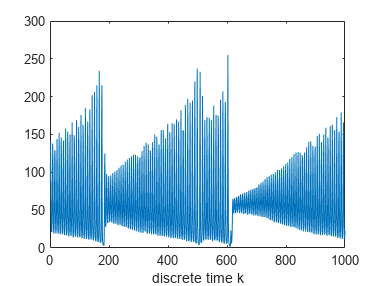

clear all
close all
lasertrain = load('lasertrain.dat');
laserpred = load('laserpred.dat');
mu = mean(lasertrain);
sigma = std(lasertrain);
lasertrain_standardized = zscore(lasertrain);
lasertest = getTimeSeriesTrainData(laserpred,1);

figure
plot(lasertrain)
xlabel("discrete time k");

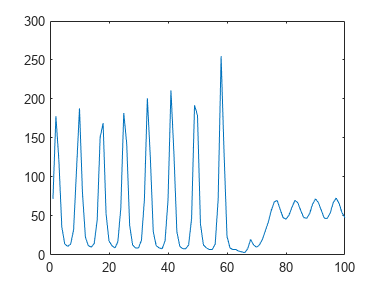

plot(laserpred)

rsme = 73.0848

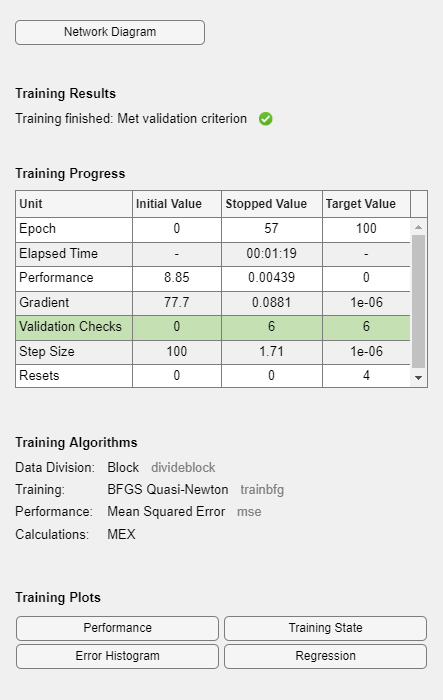

rsme =    73.0848
   91.8023





net.trainParam.epochs=100;
ps = [50];
ns = [10 30];
for n = 1:size(ns)+1
    net=feedforwardnet(ns(n),'trainbfg');
    net.divideFcn='divideblock';
    net.divideMode='sample';
    net.divideParam.trainRatio=0.8;
    net.divideParam.valRatio=0.2;
    net.divideParam.testRatio=0.0;
    net.trainParam.epochs=100;
    for p = 1:size(ps)
        [Xtrain, Ytrain] = getTimeSeriesTrainData(lasertrain_standardized, ps(p));
        net = configure(net,Xtrain,Ytrain);
        net = train(net, Xtrain, Ytrain);
        
        y_test = lasertest;
        num_test_points = length(y_test);
        y_pred = zeros(num_test_points, 1);
        input_vector = lasertrain_standardized(end-ps(p)+1:end, 1);
        
        for i = 1:num_test_points
          y_pred_standardized = net(input_vector);
          y_pred(i) = y_pred_standardized * sigma + mu;
          input_vector = [y_pred_standardized;input_vector(1:end-1)];
        end
        rsme(n,p) = sqrt(mean((y_pred-lasertest').^2))
    end 
end